clear;

fil1=transpose(load("BPNetwork1-FMP.txt")); %BP-filter brukt på I(t)
fil2=transpose(load("BPNetwork2-FMP.txt")); %BP-filter brukt på Q(t)

f1=fil1(1,:); Mag1=fil1(2,:); Phase1=fil1(3,:);
f2=fil2(1,:); Mag2=fil2(2,:); Phase2=fil2(3,:);

idx1_lower = find(abs(Mag1-max(Mag1)+3)<0.2, 1, 'first');
idx1_upper = find(abs(Mag1-max(Mag1)+3)<0.2, 1, 'last');
fc1_lower = f1(idx1_lower);
fc1_upper = f1(idx1_upper);

idx2_lower = find(abs(Mag2-max(Mag2)+3)<0.2, 1, 'first');
idx2_upper = find(abs(Mag2-max(Mag2)+3)<0.2, 1, 'last');
fc2_lower = f2(idx2_lower);
fc2_upper = f2(idx2_upper);

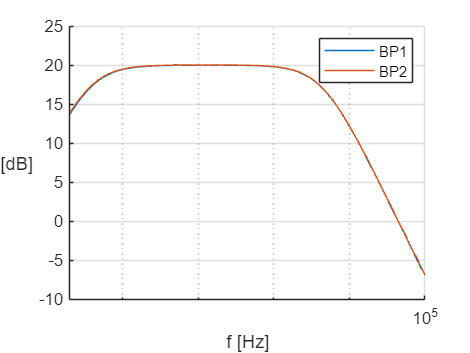

figure;
grid on;
ax = gca;
set(ax, 'XScale', 'log')
hold on;
plot(f1,Mag1,'Color',[0 0.4470 0.7410]);
plot(f2,Mag2,'Color',[0.8500 0.3250 0.0980]);
hold off;
legend("BP1","BP2");
ylabel("[dB]");
xlabel("f [Hz]"); xlim([2 10^5]);
set(get(gca,'ylabel'),'rotation',0);

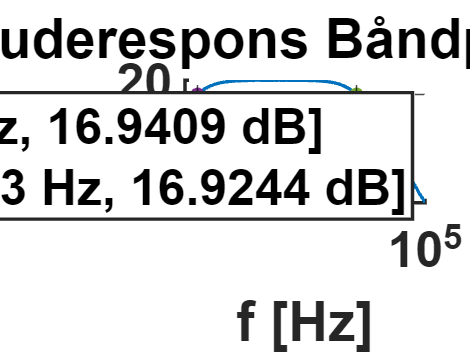

figure;
hold on;
plot(f1,Mag1,'Color',[0 0.4470 0.7410],'LineWidth',2);
xline(fc1_lower, '--k');
xline(fc1_upper, '--k');
yline(Mag1(idx1_upper),'--k')
plot(fc1_lower,Mag1(idx1_lower),'.','MarkerSize',25,'Color',[0.4940 0.1840 0.5560]);
plot(fc1_upper,Mag1(idx1_upper),'.','MarkerSize',25,'Color',[0.4660 0.6740 0.1880]);
hold off;
ylabel("[dB]");
xlabel("f [Hz]"); xlim([2 10^5]);
title('Amplituderespons Båndpassfilter #1');
lgd=legend("","","","","["+fc1_lower+" Hz, "+Mag1(idx1_lower)+" dB]","["+fc1_upper+" Hz, "+Mag1(idx1_upper)+" dB]");
lgd.FontSize=30;

ax = gca;
set(ax, 'XScale', 'log')
set(ax.YLabel,'rotation',0);
ax.LineWidth = 2;
ax.FontSize=30;
ax.FontWeight='bold';

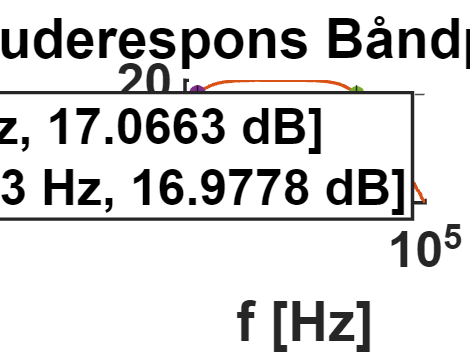

figure;
hold on;
plot(f2,Mag2,'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
xline(fc2_lower, '--k');
xline(fc2_upper, '--k');
yline(Mag2(idx2_upper),'--k')
plot(fc2_lower,Mag2(idx2_lower),'.r','MarkerSize',30,'Color',[0.4940 0.1840 0.5560]);
plot(fc2_upper,Mag2(idx2_upper),'.g','MarkerSize',30,'Color',[0.4660 0.6740 0.1880]);
hold off;
ylabel("[dB]");
xlabel("f [Hz]"); xlim([2 10^5]);
title('Amplituderespons Båndpassfilter #2');
lgd=legend("","","","","["+fc2_lower+" Hz, "+Mag2(idx2_lower)+" dB]","["+fc2_upper+" Hz, "+Mag2(idx2_upper)+" dB]");
lgd.FontSize=30;

ax = gca;
set(ax, 'XScale', 'log')
set(ax.YLabel,'rotation',0);
ax.LineWidth = 2;
ax.FontSize=30;
ax.FontWeight='bold';